# CubeSpace CubeWheel Small Characterization

For design of control systems, it is necessary to produce accurate models of how our reaction wheels will behave. The information provided by CubeSpace is very minimal and not enough information is provided to easily characterize and model the speed controller mode. As such we will only be able to model how the wheel will behave with a commanded torque from our other algorithms.

## Friction Characteristics

To characterize the viscous friction of the wheel, the torque being used to maintain steady state will be used. As there is no anticipated viscous friction when the wheel is not rotating, the resting current at this data point is considered to be constant. DC machines obey the following linear relation and therefore the current at maximum torque data point can be used find the torque-current relationship for the motor.


$$T = I_a k_t$$


v_bat = 8; % DC voltage of the battery

% Data provided by CubeSpace
tq_tq_charact = [0 0.23] * 1e-3; % Nm
pow_bat_tq_charact = [26 640] * 1e-3; % W

cur_bat_tq_charact = pow_bat_tq_charact / v_bat;

% Finds the relationship between torque and current
tq_cur_rel = polyfit(cur_bat_tq_charact, tq_tq_charact, 1)

tq_cur_rel =     0.0030   -0.0000


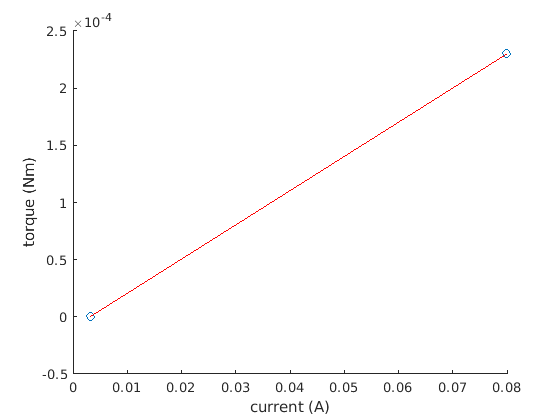


% Plots the results
hold on;
scatter(cur_bat_tq_charact, tq_tq_charact);
plot(cur_bat_tq_charact, polyval(tq_cur_rel, cur_bat_tq_charact), 'r');

xlabel("current (A)");
ylabel("torque (Nm)");
hold off;

Using the provided data for power used at various currents, the torque being provided to the motor to maintain steady state is calculated and various fits will show a model between wheel rates and viscous friction.

% Data provided by CubeSpace
rpm_vf_charact = [0 500 2000 6000]; % RPM
pow_vf_charact = [26 30 50 102] * 1e-3; % W

ang_vel_vf_charact = rpm_vf_charact * (2*pi)/60 % rad/s

ang_vel_vf_charact =          0   52.3599  209.4395  628.3185


cur_vf_charact = pow_vf_charact / v_bat;

% Using the torque-current relationship above, the steady-state current is
% calculated and is assumed to be viscous friction
tq_vf_charact = polyval(tq_cur_rel, cur_vf_charact)

tq_vf_charact = 1.0e-04 *

   -0.0000    0.0150    0.0899    0.2847



% Fits a relationship between angular velocity and the torque being exerted
% by the motor, this is opposing the viscous friction
p1 = polyfit(ang_vel_vf_charact, tq_vf_charact, 1)

p1 = 1.0e-06 *

    0.0459   -0.4854


p2 = polyfit(ang_vel_vf_charact, tq_vf_charact, 2)

p2 = 1.0e-06 *

    0.0000    0.0426   -0.3034


p3 = polyfit(ang_vel_vf_charact, tq_vf_charact, 3)

p3 = 1.0e-07 *

   -0.0000    0.0013    0.2222   -0.0000



% Fits to y=ax for identifying optimal model to use for control systems
line_fittype = fittype({'x'});
f1 = fit(ang_vel_vf_charact', tq_vf_charact', line_fittype)

f1 =      Linear model:
     f1(x) = a*x
     Coefficients (with 95% confidence bounds):
       a =   4.497e-08  (4.226e-08, 4.768e-08)

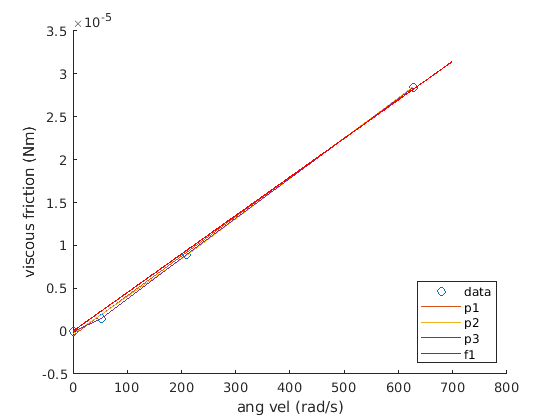

figure(2);
hold on;

scatter(ang_vel_vf_charact, tq_vf_charact);
plot(ang_vel_vf_charact, polyval(p1, ang_vel_vf_charact));
plot(ang_vel_vf_charact, polyval(p2, ang_vel_vf_charact));
plot(ang_vel_vf_charact, polyval(p3, ang_vel_vf_charact));
plot(f1);

legend('data', 'p1', 'p2', 'p3', 'f1', 'Location', 'southeast');
xlabel("ang vel (rad/s)");
ylabel("viscous friction (Nm)")

hold off;

As seen in the graph above, the linear relationship with intercept at 0 (f1) is sufficient for modelling viscous friction.

## Mechanical Characteristics

Using the values provided by CubeSpace Small, the moment of inertia around the spin axis of the reaction wheel can be calculated using the maximum momentum and speed supported by the wheel.

% Data provided by CubeSpace
max_momentum = 1.7 * 1e-3; % Nms
max_rpm = 8000; % RPM

max_ang_vel = max_rpm * 2*pi/60; % rad/s

moi_spin_axis = max_momentum / max_ang_vel % kg*m^2

moi_spin_axis = 2.0292e-06

## Modelling

### Control Systems Modelling

As there is limited data available from CubeSpace concerning the use of their controller, we will simplify the model to accept an input torque and will output the current angular velocity of each reaction wheel. This output can be immediately fed into an integrator to get the current angle of the motor although it is not necessarily useful.


$$J_{||}\dot{\omega} = T_c(t)-\tau_v\omega$$



$$J_{||}\omega(s)s = T_c(s)-\tau_c\omega(s) \longrightarrow \frac{\omega(s)}{T_c(s)}=\frac{1}{J_{||}s+\tau_v}$$


Using this definition we can construct a transfer function and simulate various input signals of our commanded torque.

s = tf('s');

% Transfer function relating the input commanded torque to output angular
% velocity of the reaction wheel
wheel_tf = 1 / (moi_spin_axis * s + f1.a)

wheel_tf =
 
             1
  -----------------------
  2.029e-06 s + 4.497e-08
 
Continuous-time transfer function.



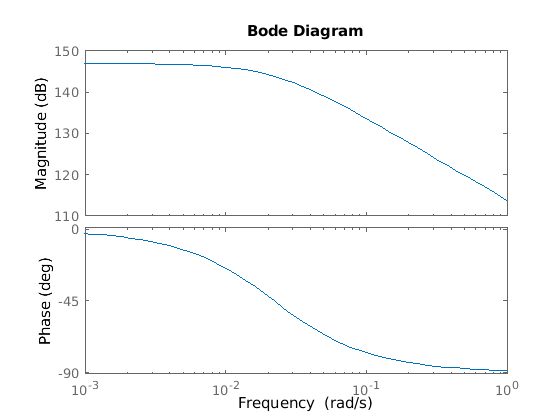

bode(wheel_tf);

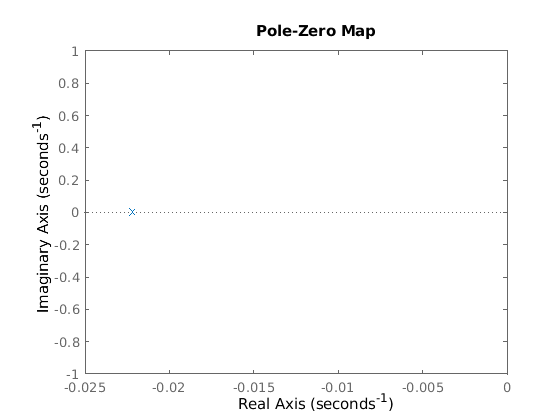

pzmap(wheel_tf);

isstable(wheel_tf)

ans = logical
   1


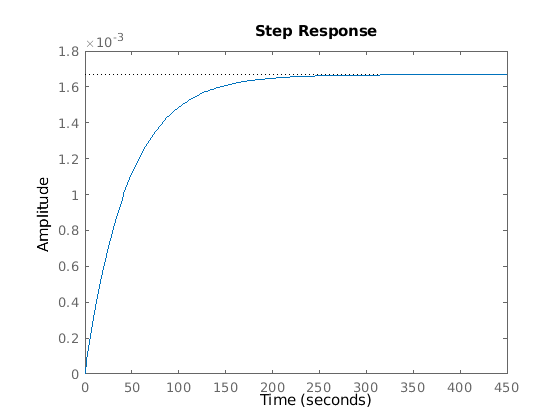

step(0.075e-9 * wheel_tf); % step signal magnitude is 0.15 mNm

It should be noted that this is an input of 0.075 nNm. If a higher torque is used the steady state response is above the 1.7 mNms maximum momentum supported by the reaction wheels. Our control systems need to take this into account and will likely need to use the magnetorquers in an active manner to prevent this issue.

% Use the more optimal state-space representation for modelling control
% systems as opposed to the Laplace-domain representation
ss(wheel_tf)

ans =
 
  A = 
             x1
   x1  -0.02216
 
  B = 
        u1
   x1  512
 
  C = 
          x1
   y1  962.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



### Disturbances Modelling

Maximum static and dynamic imbalances are provided by CubeSpace for the CubeWheel Small and are provded in their specifications as the following:

- Maximum static imbalance: < 0.003 g*cm

- Maximum dynamic imbalance: < 0.005 g*cm^2

As no other data is provided, it will be assumed that both the static and dynamic imbalances are isotropic in the wheel frame (z is aligned with the spin axis of reaction wheel in the body frame). The vectors of these imbalances also rotate with the wheel in this wheel frame.


$$A = \left[\matrix{ \cos\theta & \sin\theta & 0 \cr \sin\theta & \cos\theta & 0 \cr 0 & 0 & 1 }\right]$$



$$\dot{A} = A\left[\omega \times\right] = \left[ \matrix{\cos(\theta) & \sin(\theta) & 0 \cr \sin(\theta) & \cos(\theta) & 0 \cr 0 & 0 & 0 } \right]\left[ \matrix{0 & -\omega_3 & \omega_2 \cr \omega_3 & 0 & -\omega_1 \cr -\omega_2 & \omega_1 & 0} \right] = \omega \left[ \matrix{ \sin(\theta) & -\cos(\theta) & 0 \cr \cos(\theta) & -\sin(\theta) & 0 \cr 0 & 0 & 0} \right]$$


% These are the relevant calculations that can be made but it should be
% noted that these can not be used with linear control systems modelling as
% these are nonlinear equations based on the angular velocity
stat_imbal = 0.003 * 1e-5; % kg*m
dyn_imbal = 0.005 * 1e-7; % kg*m^2

% Starting values
ang_imbal = 0; % rad
ang_vel_imbal = pi/8; % rad/s

stat_imbal_force = -stat_imbal * ang_vel_imbal^2 * [1/sqrt(2) 1/sqrt(2) 0]' % assumes isotropic

stat_imbal_force = 1.0e-08 *

   -0.3271
   -0.3271
         0


dyn_imbal_tq = dyn_imbal * ang_vel_imbal^2 * [-1/sqrt(2) 1/sqrt(2) 0]' % assumes isotropic

dyn_imbal_tq = 1.0e-10 *

   -0.5452
    0.5452
         0


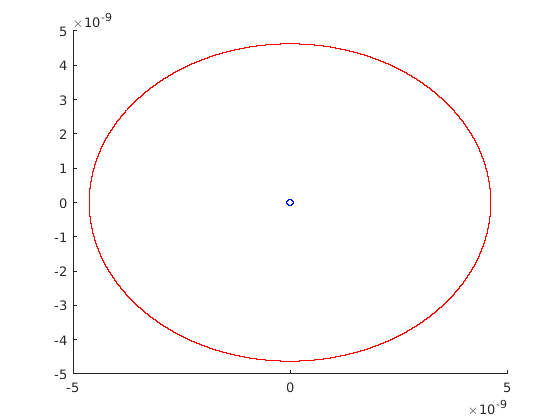

% Using a Euler timestep the change in the imbalance vectors are shown in
% the following 3-dimensional plots over a time period

timestep = 1e-5; % s
timeseries = 1000000               ; % Times to get output

stat_imbal_force_timeseries = zeros(3, timeseries);
dyn_imbal_tq_timeseries = zeros(3, timeseries);

% Rotation matrix for rotating the imbalance vectors around the spin axis
rot_matrix = [cos(ang_imbal) sin(ang_imbal) 0 ; sin(ang_imbal) cos(ang_imbal) 0 ; 0 0 1];    

for i=1:timeseries
    % Calculates the rotated imbalances
    stat_imbal_force_timeseries(:, i) = rot_matrix * stat_imbal_force;
    dyn_imbal_tq_timeseries(:, i) = rot_matrix * dyn_imbal_tq;

    % Applies Euler timestep to the rotation matrix
    d_rot_matrix = rot_matrix * [sin(ang_imbal) -cos(ang_imbal) 0 ; cos(ang_imbal) -sin(ang_imbal) 0 ; 0 0 0];
    rot_matrix = rot_matrix + d_rot_matrix * timestep;
end

figure(3);
hold on;

plot(stat_imbal_force_timeseries(1, :), stat_imbal_force_timeseries(2, :), 'r');
plot(dyn_imbal_tq_timeseries(1, :), dyn_imbal_tq_timeseries(2, :), 'b');

hold off;

It should be noted that these are forces and torques acting on the reaction wheel itself and therefore will exert an equal but opposite force and torque on the rigidbody of the satellite. They also must be rotated to match the spin axis of each reaction wheel.